% Clear history
clear;
clc;

% Set LaTeX as Interpreter for text labels
list_factory = fieldnames(get(groot,'factory'));
index_interpreter = find(contains(list_factory,'Interpreter'));
for i = 1:length(index_interpreter)
    default_name = strrep(list_factory{index_interpreter(i)},'factory','default');
    set(groot, default_name,'latex');
end

## p10

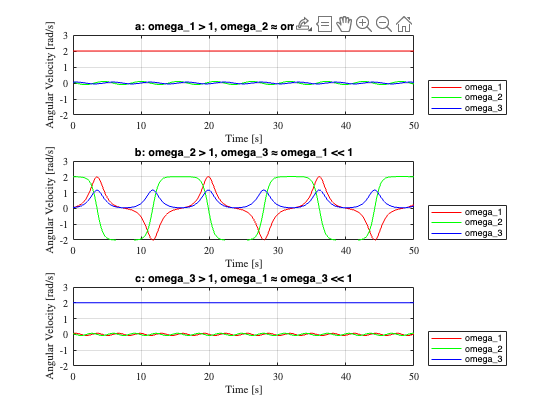

% moments of inertia
I1 = 1;
I2 = 2;
I3 = 3;

% initial conds
a_0 = [2; 0.05; 0.05];
b_0 = [0.05; 2; 0.05];
c_0 = [0.05; 0.05; 2];

% timespan
t = [0 50];

% solve with ode45
[t_a, omega_a] = ode45(@(t, omega) euler_eqns(t, omega, I1, I2, I3), t, a_0);
[t_b, omega_b] = ode45(@(t, omega) euler_eqns(t, omega, I1, I2, I3), t, b_0);
[t_c, omega_c] = ode45(@(t, omega) euler_eqns(t, omega, I1, I2, I3), t, c_0);

% plot
figure;
titles = {'a: omega_1 > 1, omega_2 ≈ omega_3 << 1','b: omega_2 > 1, omega_3 ≈ omega_1 << 1','c: omega_3 > 1, omega_1 ≈ omega_3 << 1'};
data = {t_a, omega_a; t_b, omega_b; t_c, omega_c};
for i = 1:3
subplot(3, 1, i);
t = data{i, 1};
omega = data{i, 2};
plot(t, omega(:, 1), 'r', 'DisplayName', 'omega_1');
hold on;
plot(t, omega(:, 2), 'g', 'DisplayName', 'omega_2');
plot(t, omega(:, 3), 'b', 'DisplayName', 'omega_3');
ylim([-2, 3]);
xlabel('Time [s]');
ylabel('Angular Velocity [rad/s]');
title(titles{i});
legend('Location', 'southeastoutside');
grid on;
end


% euler eqns
function d_omega = euler_eqns(~, omega, I1, I2, I3)
% Extract angular velocities
omega1 = omega(1);
omega2 = omega(2);
omega3 = omega(3);
% Compute derivatives using Euler's equations
d_omega1 = (I3 - I2) / I1 * omega2 * omega3;
d_omega2 = (I1 - I3) / I2 * omega1 * omega3;
d_omega3 = (I2 - I1) / I3 * omega1 * omega2;
% Return derivatives as a column vector
d_omega = [d_omega1; d_omega2; d_omega3];
end